**DWM, Digital Watermarking – Comparison of DCT (Cosine) and DWT (Wavelet) methods for Images**

Follow this simple Image Watermarking Procedure to control the program flow by running it section by section:

    1. Read unmarked intensity image

    2. Read the watermark (binary image)

    3. Select transformation from a drop down [None, DCT, DWT]

    4. Mark the image with a scrambled watermark, save it as .tif

    5. Attack/degrade the marked image (select an attack method from a drop down) 

    6. Browse to and Read a marked intensity image

    7. Detect and extract the watermark image, show Correlation Coefficient and BER results

*Steps 1-3 are mandatory on init, steps 3-7 are repeatable.*

Note: Unmarked image has to be grayscale. If a color image is selected, it is coverted into a grayscale image.

close all;  clc, clear variables

**0.** Initialization

K = 14;    % "watermark strength" in [%] of transformation coefficients intensity change
block_dim = 8; % DCT block size is 8x8
Level = 3; % Level of decomposition for Wavelet transformation, Level = round(log10(block_dim)/log10(2))
nfactor = 1; hdim_wmark = 1; wdim_wmark = 1; % set later to actual vals

**1.** Read unmarked intensity image 

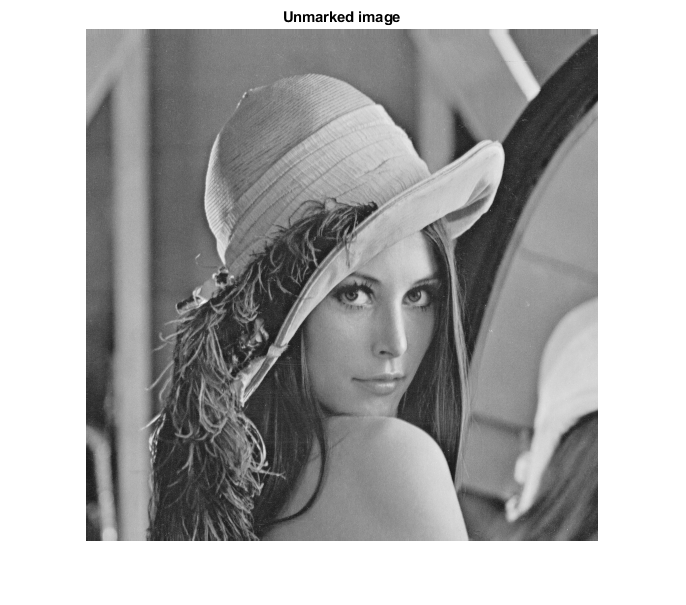

[file, path, ~] = uigetfile(fullfile(pwd,'input','*.tif;*.png;*.jpg;*.jpeg'),'Input image file selection');
if and(length(file)~=1,length(path)~=1)
    img_path = fullfile(path,file);
    Unmarked_image = imread(img_path);
    if length(size(Unmarked_image)) ~= 2
        disp('Image dimensions have to be MxN pixels.');
        Unmarked_image = rgb2gray(Unmarked_image);
        % Enter intensity/grayscale image
    end
    figure('Name',strcat("Unmarked image: ",file)), imshow(Unmarked_image), title('Unmarked image')
    [Image, Vs, Ss] = adj_image(Unmarked_image, block_dim);
    nfactor = norm_factor(Image);
    Image = double(Image)/nfactor;
    % Watermark dimensions
    hdim_wmark = Vs/block_dim;
    wdim_wmark = Ss/block_dim;
    hw_wmark = hdim_wmark * wdim_wmark;
end

**2.** Read watermark (binary image with pixels 0 or 1) 

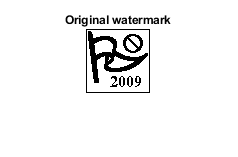

[file, path, ~] = uigetfile(fullfile(pwd,'input','*.jpeg;*.png;*.jpg;*.tif'),'Input watermark image file selection');
if and(length(file)~=1,length(path)~=1)
    watermark_path = fullfile(path,file); %'input\\watermark.jpeg';
    tmp_wmark = imread(watermark_path);
    orig_wmark = zeros(size(tmp_wmark));
    tmp_wmark = tmp_wmark/max(max(tmp_wmark));
    above = find(tmp_wmark >= 0.5);
    orig_wmark(above) = ones(size(above));
    figure('Name',strcat("Original watermark: ",file)), imshow(orig_wmark), title('Original watermark')
    watermark = adj_wmark(orig_wmark, hdim_wmark, wdim_wmark);
end

**3. **Select method (None, DCT or Wavelet)

method = 'DWT'

method = 'DWT'

**4.** Mark an image (incorporate the watermark) 

Note: MATLAB's pseudorandom number generator (PRNG) is set to init state def by the `key` that permutes/scrambles the `watermark`

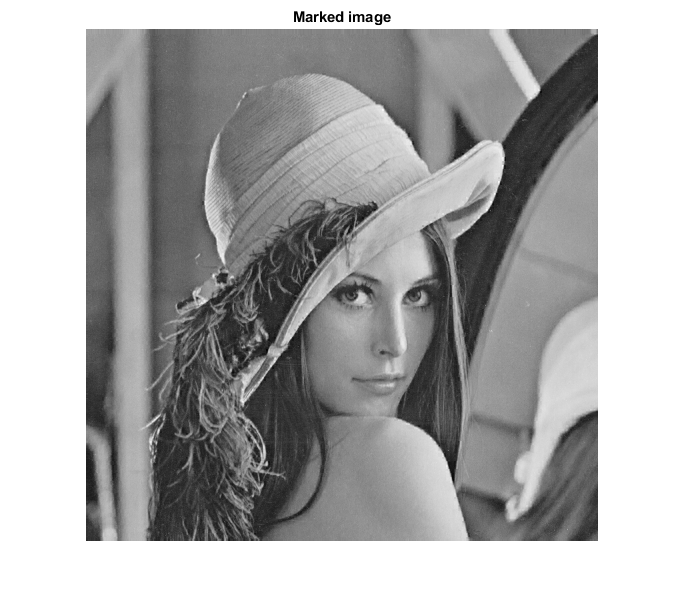

if evalin( 'base', 'exist(''hw_wmark'',''var'') == 1' )
    % check if image file/var is loaded.
    if evalin( 'base', 'exist(''watermark'',''var'') == 1' )
        % check if watermark file/var is loaded.
        if evalin( 'base', 'exist(''method'',''var'') == 1' )
            % check if method is selected.
            % Key for PSS generator
            key = 1682004;
            % MATLAB PSS generator is set to init state def by the key
            rng(key);
            % PSS Permute the watermark
            a1 = randperm(hw_wmark);
            clear key; % delete key
            a2 = reshape(a1, hdim_wmark, wdim_wmark);
            
            scrambled_wmark = watermark(a2);
            scrambled_wmark_norm = (scrambled_wmark - 0.5)/0.5; % range [-1,1]
            % % scrambled_wmark_norm is type double
            
            file_name = 'Marked_image';
            switch method
                case 'DCT'
                Marked_image = embed_DCT(Image, scrambled_wmark_norm, block_dim, K);
                case 'DWT'
                Marked_image = embed_DWT(Image, scrambled_wmark_norm, Level, K);
                otherwise
                disp('Not marked. Watermark method: None.')
                Marked_image = Image;
            end
            default_file = fullfile(fullfile(fullfile(pwd,'output'),'marked'),strcat(file_name,'_', method, '.tif'));
            [file, path, ~] = uiputfile(('*.tif;*.png;*.jpg;*.jpeg'),'Marked image file Save As', default_file);
            if and(length(file)~=1,length(path)~=1)
                file_path = fullfile(path,file);
                figure('Name',strcat("Marked image: ",file)), imshow(Marked_image), title('Marked image')
                Marked_image_uint8 = uint8(Marked_image * nfactor);
                imwrite(Marked_image_uint8, file_path);
            end
        else
            disp('Method not selected.')
        end
    else
        disp('Watermark file not loaded.')
    end
else
    disp('Image file not loaded.')
end

  **5.** Attak/degrade the image (just one selection for simplicity): 'None', 'JPEG compression', 'Brightness', 'Contrast', 'Cropping', 'Filtering', 'Noise'

if evalin( 'base', 'exist(''Marked_image'',''var'') == 1' )
    % check if image file/var is loaded.
    attack = 'Cropping'
    switch attack
        case 'JPEG compression'
            output_folder = uigetdir(fullfile(pwd,'output'),'Output folder selection');
            attack = compression(Marked_image_uint8, output_folder);
            %generates images that start with: JPEG_Mkd_img_
        case 'Brightness'
            output_folder = uigetdir(fullfile(pwd,'output'),'Output folder selection');
            attack = brightness(Marked_image, output_folder, nfactor);
            %generates images that start with: Bright_Mkd_img_
        case 'Contrast'
            output_folder = uigetdir(fullfile(pwd,'output'),'Output folder selection');
            attack = contrast(Marked_image, output_folder, nfactor);
            %generates images that start with: Mcon_Mkd_img_
            %generates images that start with: Hcon_Mkd_img_
        case 'Cropping'
            output_folder = uigetdir(fullfile(pwd,'output'),'Output folder selection');
            attack = cropping(Marked_image_uint8, output_folder);
            %generates images that start with: Vcrop_Mkd_img_
            %generates images that start with: VScrop_Mkd_img_
        case 'Filtering'
            output_folder = uigetdir(fullfile(pwd,'output'),'Output folder selection');
            attack = filtering(Marked_image_uint8, output_folder);
            %generates images that start with: Filt_Mkd_img_
        case 'Noise'
            output_folder = uigetdir(fullfile(pwd,'output'),'Output folder selection');
            attack = noise(Marked_image_uint8, output_folder);
            %generates images that start with: Noise_Mkd_img_
        otherwise
            disp('Not attacked. Attack method: None.')
    end
end

attack = 'Cropping'

**6.** Read marked intensity/grayscale image 

C:\Users\dzoni\Documents\GitHub\watermark\output\cropped\Vcrop_Mkd_img_4.tif


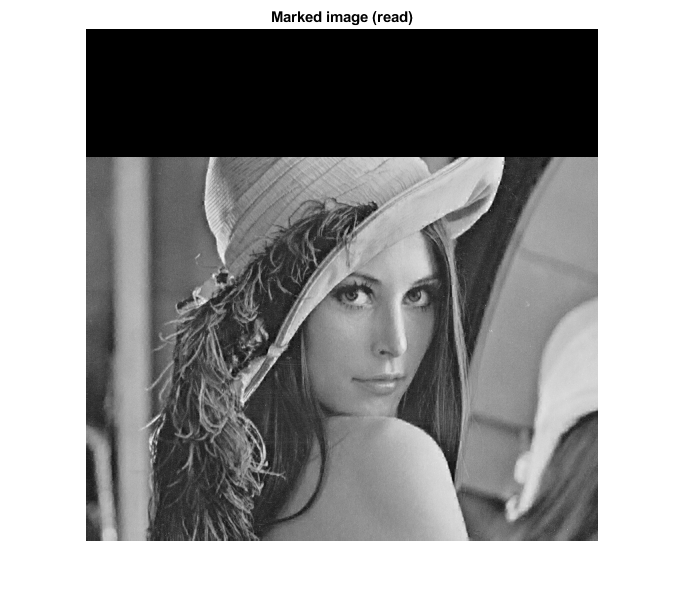

[file, path, index] = uigetfile(fullfile(pwd,'output','*.tif;*.png;*.jpg;*.jpeg'),'Marked intensity/grayscale image selection');
if and(length(file)~=1,length(path)~=1)
    full_path = fullfile(path,file);
    disp(full_path);
    Marked_image = imread(full_path);
    if length(size(Marked_image)) ~= 2
        disp('Image dimensions have to be MxN pixels.');
        Marked_image = rgb2gray(Marked_image); % convert to grayscale
    end
    nfactor = norm_factor(Marked_image);
    Marked_image = double(Marked_image)/nfactor;
    % Dimensions of unmarked and marked image are the same.
    figure('Name', strcat("Marked image (read): ",file)), imshow(Marked_image), title('Marked image (read)')
end

**7**. Detect watermark 

Note: Use again the same `key` for MATLAB's pseudorandom number generator (PRNG) to unscramble the `watermark`

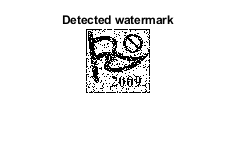


 Correlation Coefficient of the watermarks   0.751151


 Normalized Correlation of the watermarks   0.888425


 Correlation Coefficient of the images   0.517765


 Normalized Correlation of the images   0.738132  



 Num of bit errors in detected watermark 478   


 BER [%] for detected watermark 11.669922  


*******************************************************


if evalin( 'base', 'exist(''hw_wmark'',''var'') == 1' )
    % check if image file/var is loaded.
    if evalin( 'base', 'exist(''watermark'',''var'') == 1' )
        % check if watermark file/var is loaded.
        if evalin( 'base', 'exist(''method'',''var'') == 1' )
            % check if method is selected.
            % Key for MATLAB's pseudorandom number generator (PRNG)
            key = 1682004;
            %key = input('\n Enter the password:   ');
            rng(key);
            % Undo the permutation of the watermark.
            b1 = randperm(hw_wmark);
            clear key; % delete key
            b2 = reshape(b1, hdim_wmark, wdim_wmark);
            switch method
                case 'DCT'
                recovered_watermark = extract_DCT(Image, Marked_image, b2, block_dim, hdim_wmark, wdim_wmark);
                case  'DWT'
                recovered_watermark = extract_DWT(Image, Marked_image, b2, Level, nfactor, hdim_wmark, wdim_wmark);
                otherwise
                disp('Not detected. Watermark method: None.')
                Marked_image = Image;
                recovered_watermark = watermark*0;
            end
            figure('Name',strcat("Detected watermark from: ",file)),imshow(recovered_watermark),title('Detected watermark')
            CC_wmark = corr2(watermark, recovered_watermark);
            fprintf('\n Correlation Coefficient of the watermarks   %f', CC_wmark)
            NC_wmark = sum(sum(recovered_watermark .* watermark))/sum(sum(watermark.^2));
            fprintf('\n Normalized Correlation of the watermarks   %f', NC_wmark)
            CC_img = corr2(Image, Marked_image);
            fprintf('\n Correlation Coefficient of the images   %f', CC_img)
            NC_img = sum(sum(Marked_image .* Image))/sum(sum(Image.^2));
            fprintf('\n Normalized Correlation of the images   %f  \n', NC_img)
            error = abs(recovered_watermark - watermark);
            TotErrBits = sum(sum(error));
            fprintf('\n Num of bit errors in detected watermark %i   ', TotErrBits)
            TotErrBitsPercent = (TotErrBits/hw_wmark)*100;
            fprintf('\n BER [%%] for detected watermark %f  \n', TotErrBitsPercent)
            disp('*******************************************************')
        else
            disp('Method not selected.')
        end
    else
        disp('Watermark file not loaded.')
    end
else
    disp('Image file not loaded.')
end

Ver.1.0 2009, 1.2 2020, 1.2.x 2021, 2023

Author: Nikola Jovanovic

Repo: [https://github.com/etfovac/watermark](https://github.com/etfovac/watermark) 

[https://www.mathworks.com/matlabcentral/fileexchange/78790-digital-watermarking-comparison-of-dct-and-dwt-methods](https://www.mathworks.com/matlabcentral/fileexchange/78790-digital-watermarking-comparison-of-dct-and-dwt-methods) 